clear all;close all;
addpath(genpath('C:\Users\Kamphausen\sciebo\ZnSe\Matlab script'))
%just open folder with data in it in matlab and run the script
%make sure the filename is like date_sample_structures_contactspecification(_size).format
format='*.txt';            %fileformat that is currently processed is .txt
N=20;                      %fit from ni-N to ni+N
n=1;                       %degree of fitpolynome
M=2;                       %Fitmodel for full curve
safeplots=0;               %1: safe 0: dont safe
plottitle='All';   %Plottitle for plot with all curves
poi='zero';                  %POI for evaluation at either 'zero' or 'max'=10V

illum=0;                    %0 for no illumination, 1 for illumination

%   find xls file from the directory that is currently openend in MATLAB
filestruct=dir(format);
files={filestruct.name};


% Distance between contacts L, Circumference of contacts U and Area of contacts A.
L=zeros(1,length(files));
U=zeros(1,length(files));
A=zeros(1,length(files));
for i=1:length(files)
    C = regexp(char(files(i)), '_', 'split');
    sample=string(C{2});
    structure=string(C{3});
    field=char(C{4});
    if structure=='TLM'
        L(i) = str2num(C{4});
    elseif structure=='Stripes'
        L(i) = 200;
        try
            size=char(C{5});
            size=size(1:end-4);
        catch
            field=field(1:end-4);
            switch field
                case '7-7'
                    U(i)=1.7;  A(i)=0.04;
                case '8-8'
                    U(i)=3.7;  A(i)=0.09;
                case '9-9'
                    U(i)=2.55;  A(i)=0.09;
                case '10-10'
                    U(i)=4.416;  A(i)=0.16;
            end
        end
        switch field
            case '1-1'
                switch size
                    case 'S'
                        U(i)=0.3;  A(i)=0.005;
                    case 'M'
                        U(i)=0.35; A(i)=0.0075;
                    case 'L'
                        U(i)=0.4;  A(i)=0.01;
                end
            case '2-2'
                switch size
                    case 'S'
                        U(i)=0.4;  A(i)=0.0075;
                    case 'M'
                        U(i)=0.45; A(i)=1.5*0.0075;
                    case 'L'
                        U(i)=0.5;  A(i)=2*0.0075;
                end
                
            case '3-3'
                switch size
                    case 'S'
                        U(i)=0.5;  A(i)=0.01;
                    case 'M'
                        U(i)=0.55; A(i)=1.5*0.01;
                    case 'L'
                        U(i)=0.6;  A(i)=0.02;
                end
                
            case '4-4'
                switch size
                    case 'S'
                        U(i)=0.7;  A(i)=0.015;
                    case 'M'
                        U(i)=0.75; A(i)=1.5*0.015;
                    case 'L'
                        U(i)=0.8;  A(i)=0.03;
                end
                
            case '5-5'
                switch size
                    case 'S'
                        U(i)=0.9;  A(i)=0.02;
                    case 'M'
                        U(i)=0.95; A(i)=1.5*0.02;
                    case 'L'
                        U(i)=1.0;  A(i)=0.04;
                end
                
            case '6-6'
                switch size
                    case 'S'
                        U(i)=1.1;  A(i)=0.025;
                    case 'M'
                        U(i)=1.15; A(i)=1.5*0.025;
                    case 'L'
                        U(i)=1.2;  A(i)=0.05;
                end
        end
    elseif structure=='Areas'
        field=field(1:end-4);
        switch field
            case '1-1'
                U(i)=0.4; A(i)=0.01;
            case '2-2'
                U(i)=0.6; A(i)=0.0225;
            case '3-3'
                U(i)=0.8; A(i)=0.04;
            case '4-4'
                U(i)=1.2; A(i)=0.09;
            case '5-5'
                U(i)=1.6; A(i)=0.16;
            case '6-6'
                U(i)=2.0; A(i)=0.25;
        end
    end
end



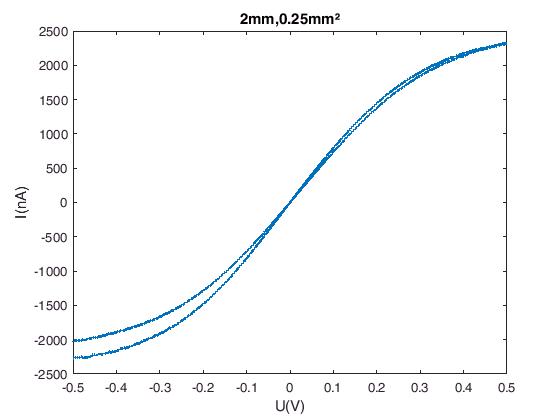

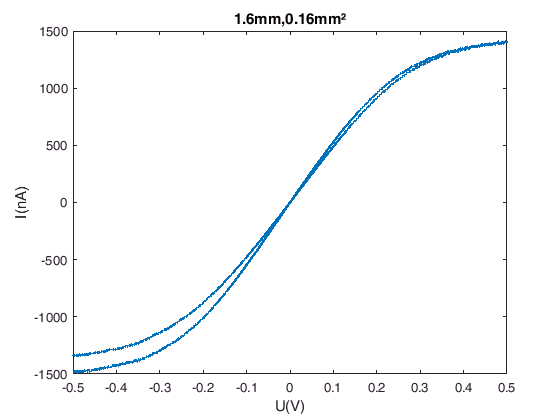

%Plots

legendL={};
for i=1:length(files)
    fig=figure();
    Data=importdata(char(files(i)));   % data file
    Data.data(:,[1 2]) = Data.data(:,[2 1]);
    plot(Data.data(:,1) , 10^9*Data.data(:,2),'LineWidth',2);
    if structure=='TLM'
        title(strcat(string(L(i)),'µm'));
        legendL=[legendL,char(strcat(string(L(i)),'µm'))];
    else
        title(strcat(string(U(i)),'mm',', ',string(A(i)),'mm²'));
        legendL=[legendL,char(strcat(string(U(i)),'mm',', ',string(A(i)),'mm²'))];
    end
    xlabel('U(V)');
    ylabel('I(nA)');
    hold off
    if safeplots==1
        mkdir('plots/single');
        saveas(fig,['plots/single/' char(files(i)) '.pdf']);
    end
end

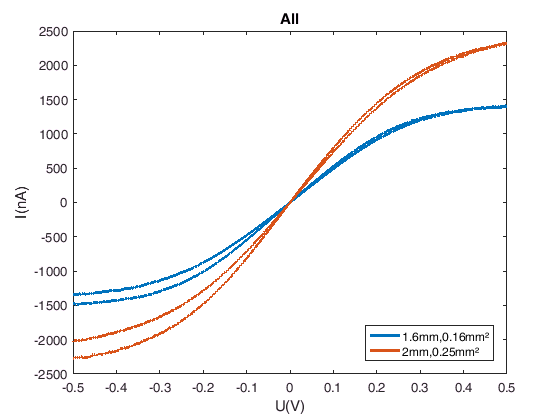


for i=1:length(files)
    Data=importdata(char(files(i)));
    Data.data(:,[1 2]) = Data.data(:,[2 1]);
    plot(Data.data(:,1) , 10^9*Data.data(:,2),'LineWidth',2);
    hold on
end

xlabel('U(V)');
ylabel('I(nA)');
title(plottitle);

legend(legendL,'Location','southeast');


if safeplots==1
    saveas(fig,'plots/all_distances.pdf');
end

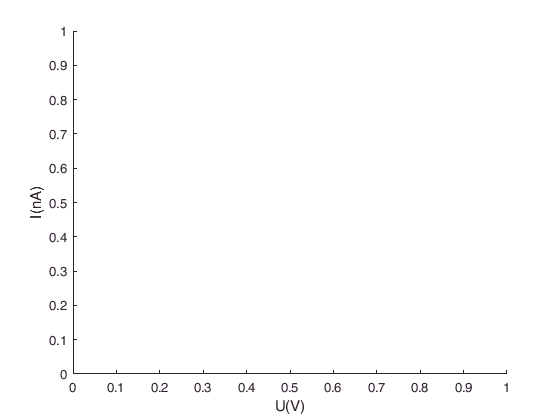

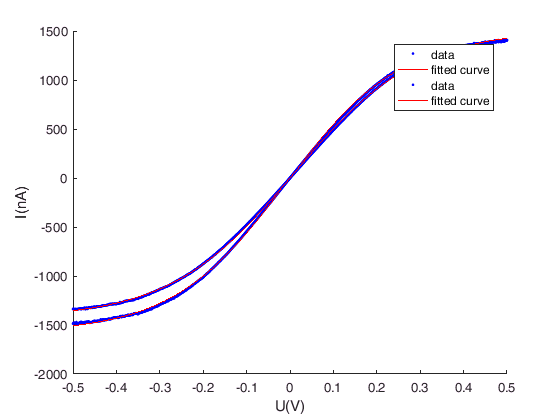

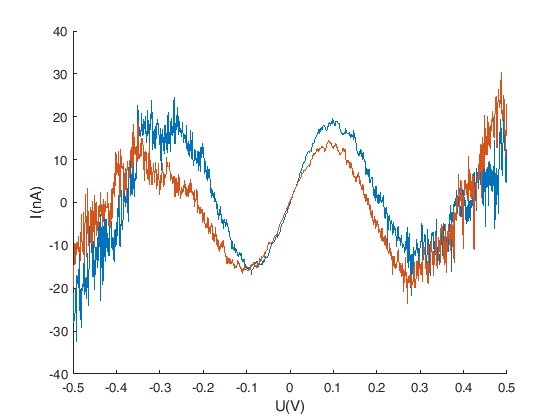

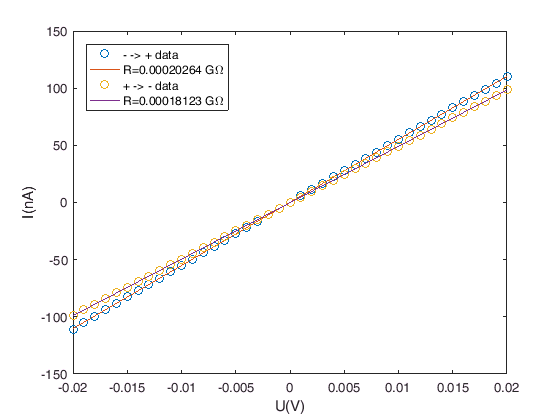

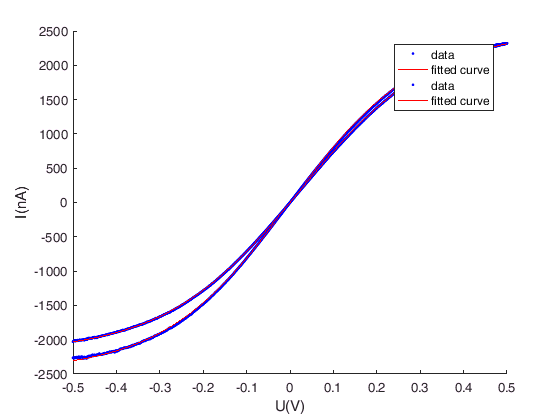

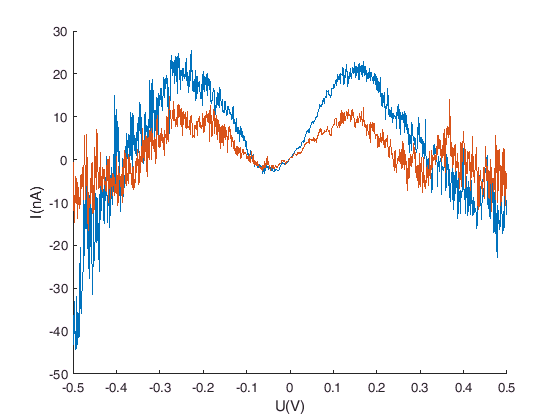

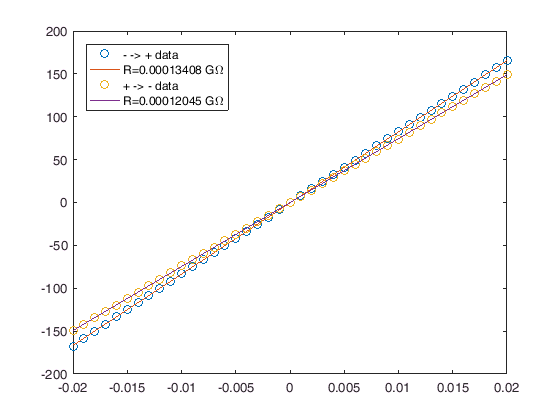

%Fitting

R=zeros(length(files),2);
dR=zeros(length(files),2);
fitcoeff=zeros(length(files),3,2);
fig2=figure();
for i=1:length(files)
    
    xlabel('U(V)');
    ylabel('I(nA)');
    hold on
    
    Data=importdata(char(files(i)));
    Data.data(:,[1 2]) = Data.data(:,[2 1]);
    
    if poi==string('zero')
        
        databluename=string('- -> + data');
        dataredname=string('+ -> - data');
        
        n1=round(1/4*length(Data.data));    %U=0 datapoint
        n2=round(3/4*length(Data.data));    %U=0 datapoint
        N_max=n1-1;
        
        fitdat1=[Data.data((n1-N_max):(n1+N_max),1),10^9*Data.data((n1-N_max):(n1+N_max),2)];
        fitdat2=[Data.data((n2-N_max):(n2+N_max),1),10^9*Data.data((n2-N_max):(n2+N_max),2)];
        
        %fitdat1U=Data.data((n1-N):(n1+N),1);
        %fitdat1I=Data.data((n1-N):(n1+N),2);
        %fitdat1Ilog=log(Data.data((n1-N):(n1+N),2));
        
        polyfitdat1=[Data.data((n1-N):(n1+N),1),10^9*Data.data((n1-N):(n1+N),2)];
        polyfitdat2=[Data.data((n2-N):(n2+N),1),10^9*Data.data((n2-N):(n2+N),2)];
        
        fig2=figure();
        if structure=='TLM'
            title(strcat(string(L(i)),'µm'));
        else
            title(strcat(string(U(i)),'mm',', ',string(A(i)),'mm²'));
        end
        
        %     Linear fit
        %
        %     scatter(polyfitdat1(:,1),polyfitdat1(:,2));
        %     scatter(polyfitdat2(:,1),polyfitdat2(:,2));
        %     h=lsline;
        %
        %     R(i,1)=(h(1,1).XData(2)-h(1,1).XData(1))/(h(1,1).YData(2)-h(1,1).YData(1));
        %     R(i,2)=(h(1,2).XData(2)-h(1,2).XData(1))/(h(1,2).YData(2)-h(1,2).YData(1));
        %
        %     legend(strcat('R=',string(R(i,2)),' G\Omega'),strcat('R=',string(R(i,1)),' G\Omega'),'Location','northwest')
        
        %    Polynomial fit
        [p1,S1]=polyfit(polyfitdat1(:,1),polyfitdat1(:,2),n); % - -> + sweep
        [p2,S2]=polyfit(polyfitdat2(:,1),polyfitdat2(:,2),n); % + -> - sweep
        
        f1=polyval(p1,polyfitdat1(:,1));
        f2=polyval(p2,polyfitdat2(:,1));
        
        %    Diode Model fit U(I)=t1 ln(I/I1+1) + t2 ln(I/I2+1) + R*I
        
        %         type = fittype(@(a,b,c,d,e,in) VImodel(in,M,[a,b,c,d,e]),'independent',{'in'},'coefficients',{'a','b','c','d','e'});
        %         type=fittype(@(I,t1,t2,I1,I2,R) VImodel(I,t1,t2,I1,I2,R))
        type=fittype(@(Is1,Is2,E,in) VImodel(in,M,[Is1,Is2,E]),'independent',{'in'},'coefficients',{'Is1','Is2','E'});
        
        fitted1=fit(fitdat1(:,1),fitdat1(:,2),type,'StartPoint', [2e3, 2e3, 20]);
        fitted2=fit(fitdat2(:,1),fitdat2(:,2),type,'StartPoint', [2e3, 2e3, 20]);
        
        %plot the fit
        fgiure1=figure();
        
        hold on
        plot(fitted1,fitdat1(:,1),fitdat1(:,2));
        plot(fitted2,fitdat2(:,1),fitdat2(:,2));
        xlabel('U(V)');
        ylabel('I(nA)');
        
        %give out fit params
        coeffnames(type);
        fitcoeff(i,:,1)=coeffvalues(fitted1);
        fitcoeff(i,:,2)=coeffvalues(fitted2);
      
        %plot the residuals
        figure2=figure();
        xlabel('U(V)');
        ylabel('I(nA)');
        hold on
        plot(fitdat1(:,1),fitted1(fitdat1(:,1))-fitdat1(:,2));
        plot(fitdat2(:,1),fitted2(fitdat2(:,1))-fitdat2(:,2));
        
        %inv(S#.R)*inv(S#.R)')*S#.normr^2/S#.df covariance matrix
        covp1=(inv(S1.R)*inv(S1.R)')*S1.normr^2/S1.df;
        covp2=(inv(S2.R)*inv(S2.R)')*S2.normr^2/S2.df;
        dp1=sqrt(covp1(n,n));
        dp2=sqrt(covp2(n,n));
        
        R(i,1)=1/p1(n);
        dR(i,1)=dp1/p1(n)^2;
        R(i,2)=1/p2(n);
        dR(i,2)=dp2/p2(n)^2;
        
        figure(fig2);
        plot(polyfitdat1(:,1),polyfitdat1(:,2),'o',polyfitdat1(:,1),f1,'-',polyfitdat2(:,1),polyfitdat2(:,2),'o',polyfitdat2(:,1),f2,'-');
        legend('- -> + data',strcat('R=',string(R(i,2)),' G\Omega'),'+ -> - data',strcat('R=',string(R(i,1)),' G\Omega'),'Location','northwest')
        
        if safeplots==1
            mkdir('plots/fits');
            saveas(fig2,['plots/fits/' char(files(i)) '.pdf']);
        end
    elseif poi==string('max')
        
        databluename=string('@-10V');
        dataredname=string('@10V');
        
        n1=round(1);    %U=-10V datapoint1
        n2=round(length(Data.data));    %U=-10V datapoint2
        n3=round(1/2*length(Data.data));    %U=10V datapoint1
        n4=round(1/2*length(Data.data))-1;    %U=10V datapoint2
        
        R(i,1)=10^-9*(Data.data(n1,1)/Data.data(n1,2)+Data.data(n2,1)/Data.data(n2,2))/2;
        R(i,2)=10^-9*(Data.data(n3,1)/Data.data(n3,2)+Data.data(n4,1)/Data.data(n4,2))/2;
        dR(i,1)=R(i,1)*0.01;
        dR(i,2)=R(i,2)*0.01;
    end
    
    
end

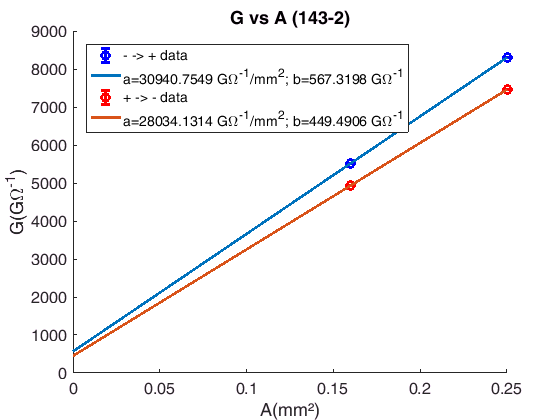

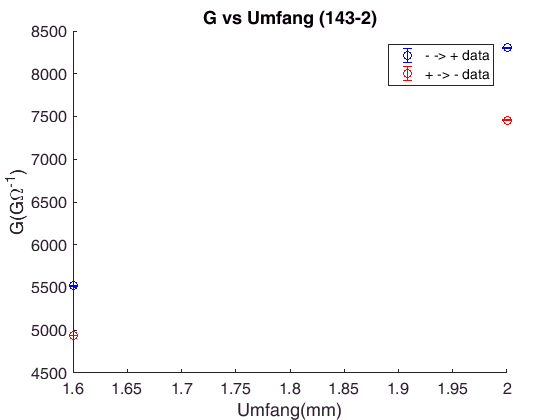

%Plotting and fitting results for R
fig3=figure('DefaultAxesFontSize',12);
hold on
if structure=='TLM'
    errorbar(L(:),R(:,1),dR(:,1),'bo'); errorbar(L(:),R(:,2),dR(:,2),'ro')
    title(strcat('R vs d (',sample,')'));
    xlabel('d(µm)');
    ylabel('R(G\Omega)');

        legend(databluename,dataredname,'Location','northeast')
else
    if illum==0
        [G1_fit_A,SG1A]=polyfit(A(:),1./R(:,1),1); % - -> + sweep
        [G2_fit_A,SG2A]=polyfit(A(:),1./R(:,2),1); % + -> - sweep
        
        A2=linspace(0,0.25);
        G1=polyval(G1_fit_A,A2(:));
        G2=polyval(G2_fit_A,A2(:));
        errorbar(A(:),1./R(:,1),dR(:,1)./R(:,1).^2,'bo','LineWidth',2);
        plot(A2(:),G1,'LineWidth',2);
        errorbar(A(:),1./R(:,2),dR(:,2)./R(:,1).^2,'ro','LineWidth',2);
        plot(A2(:),G2,'LineWidth',2);
        legend(databluename,strcat('a=',string(G1_fit_A(1)),' G\Omega^{-1}/mm^{2}','; b=',string(G1_fit_A(2)),' G\Omega^{-1}'),dataredname,strcat('a=',string(G2_fit_A(1)),' G\Omega^{-1}/mm^{2}','; b=',string(G2_fit_A(2)),' G\Omega^{-1}'),'Location','northwest');
    else
        errorbar(A(:),1./R(:,1),dR(:,1)./R(:,1).^2,'bo','LineWidth',2);
        errorbar(A(:),1./R(:,2),dR(:,2)./R(:,1).^2,'ro','LineWidth',2);
        legend(databluename,dataredname,'Location','northeast')
    end
    title(strcat('G vs A (',sample,')'));
    xlabel('A(mm²)');
    ylabel('G(G\Omega^{-1})');
    fig4=figure('DefaultAxesFontSize',12);
    hold on
    if illum==1
        [G1_fit_U,SG1U]=polyfit(U(:),1./R(:,1),1); % - -> + sweep
        [G2_fit_U,SG2U]=polyfit(U(:),1./R(:,2),1); % + -> - sweep
        
        U2=linspace(0,2);
        G1=polyval(G1_fit_U,U2(:));
        G2=polyval(G2_fit_U,U2(:));
        errorbar(U(:),1./R(:,1),dR(:,1)./R(:,1).^2,'bo');
        plot(U2(:),G1,'LineWidth',2);
        errorbar(U(:),1./R(:,2),dR(:,2)./R(:,1).^2,'ro');
        plot(U2(:),G2,'LineWidth',2);
        legend(databluename,strcat('a=',string(G1_fit_U(1)),' G\Omega^{-1}/mm^{2}','; b=',string(G1_fit_U(2)),' G\Omega^{-1}'),dataredname,strcat('a=',string(G2_fit_U(1)),' G\Omega^{-1}/mm^{2}','; b=',string(G2_fit_U(2)),' G\Omega^{-1}'),'Location','northwest')
    else
        errorbar(U(:),1./R(:,1),dR(:,1)./R(:,1).^2,'bo');
        errorbar(U(:),1./R(:,2),dR(:,2)./R(:,1).^2,'ro');
        legend(databluename,dataredname,'Location','northeast')
    end
    title(strcat('G vs Umfang (',sample,')'));
    xlabel('Umfang(mm)');
    ylabel('G(G\Omega^{-1})');
    if safeplots==1
        mkdir('plots/fits');
        saveas(fig3,['plots/fits/G_vs_A.pdf']);
        saveas(fig4,['plots/fits/G_vs_Umfang.pdf']);
    end
end

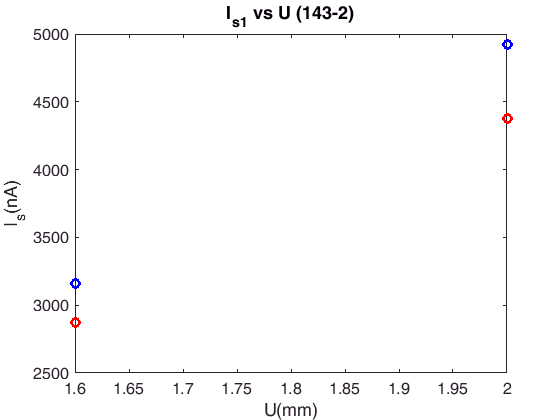


%PLotting coefficients of Model fit vs A/U/d
fig6=figure('DefaultAxesFontSize',12);
plot(U,fitcoeff(:,1,1),'bo','LineWidth',2);
hold on
plot(U,fitcoeff(:,1,2),'ro','LineWidth',2);
hold off
title(strcat('I_{s1} vs U (',sample,')'));
xlabel('U(mm)');
ylabel('I_s(nA)');

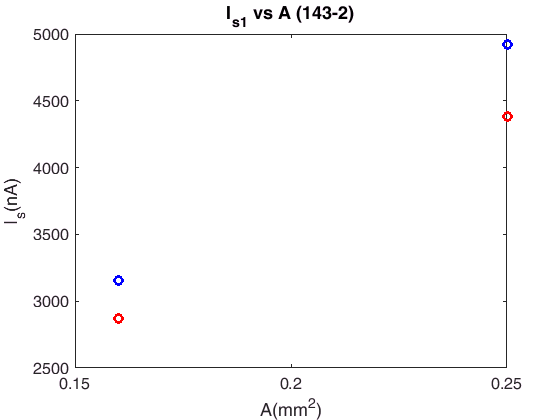


fig7=figure('DefaultAxesFontSize',12);
plot(A,fitcoeff(:,1,1),'bo','LineWidth',2);
hold on
plot(A,fitcoeff(:,1,2),'ro','LineWidth',2);
hold off
title(strcat('I_{s1} vs A (',sample,')'));
xlabel('A(mm^2)');
ylabel('I_s(nA)');

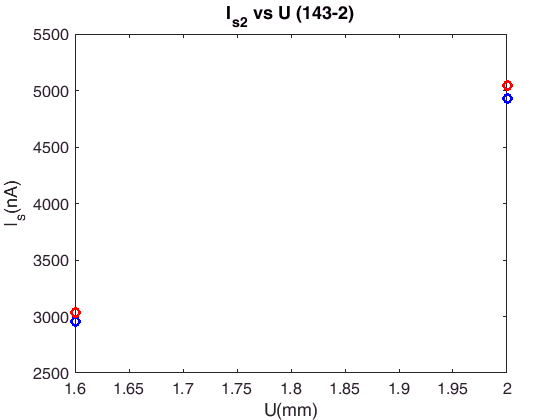


fig8=figure('DefaultAxesFontSize',12);
plot(U,fitcoeff(:,2,1),'bo','LineWidth',2);
hold on
plot(U,fitcoeff(:,2,2),'ro','LineWidth',2);
hold off
title(strcat('I_{s2} vs U (',sample,')'));
xlabel('U(mm)');
ylabel('I_s(nA)');

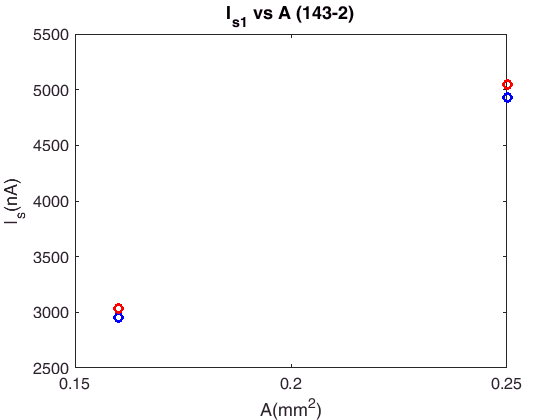


fig9=figure('DefaultAxesFontSize',12);
plot(A,fitcoeff(:,2,1),'bo','LineWidth',2);
hold on
plot(A,fitcoeff(:,2,2),'ro','LineWidth',2);
hold off
title(strcat('I_{s1} vs A (',sample,')'));
xlabel('A(mm^2)');
ylabel('I_s(nA)');

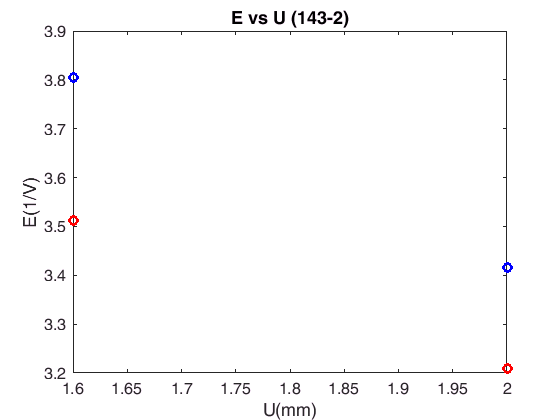


fig10=figure('DefaultAxesFontSize',12);
plot(U,fitcoeff(:,3,1),'bo','LineWidth',2);
hold on
plot(U,fitcoeff(:,3,2),'ro','LineWidth',2);
hold off
title(strcat('E vs U (',sample,')'));
xlabel('U(mm)');
ylabel('E(1/V)');

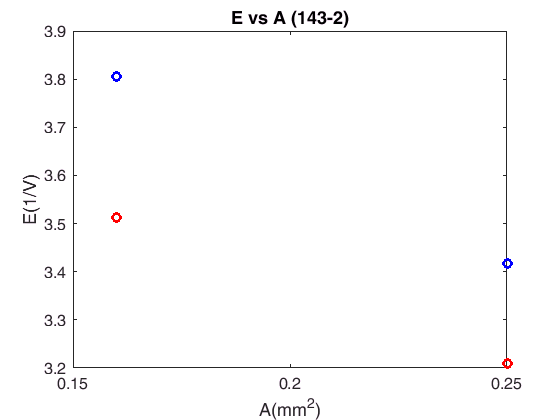


fig11=figure('DefaultAxesFontSize',12);
plot(A,fitcoeff(:,3,1),'bo','LineWidth',2);
hold on
plot(A,fitcoeff(:,3,2),'ro','LineWidth',2);
hold off
title(strcat('E vs A (',sample,')'));
xlabel('A(mm^2)');
ylabel('E(1/V)');



if safeplots==1
        mkdir('plots/fits');
        saveas(fig6,['plots/fits/Is1_vs_U.pdf']);
        saveas(fig7,['plots/fits/Is1_vs_A.pdf']);
        saveas(fig8,['plots/fits/Is2_vs_U.pdf']);
        saveas(fig9,['plots/fits/Is2_vs_A.pdf']);
        saveas(fig10,['plots/fits/E_vs_U.pdf']);
        saveas(fig11,['plots/fits/E_vs_A.pdf']);
end


%weighted mean
if structure=='TLM'
    % R_mean=sum(sum(R*1./dR))/(sum(sum(1./dR)))
    % sigma=sqrt(sum(sum(1./dR))/(sum(sum(1./(dR.^2)))))
    % errorbar(100,R_mean,sigma,'go');
    [R1_fit,SR1]=polyfit(L(:),R(:,1),1); % - -> + sweep
    [R2_fit,SR2]=polyfit(L(:),R(:,2),1); % + -> - sweep
    
    covR1=(inv(SR1.R)*inv(SR1.R)')*SR1.normr^2/SR1.df;                %errors for the fitparameters
    covR2=(inv(SR2.R)*inv(SR2.R)')*SR2.normr^2/SR2.df;
    drho1=sqrt(covR1(1,1));
    dRC1=sqrt(covR1(2,2));
    drho2=sqrt(covR2(1,1));
    dRC2=sqrt(covR2(2,2));
    
    L2=linspace(0,190);
    R1=polyval(R1_fit,L2(:));
    R2=polyval(R2_fit,L2(:));
    fig5=figure('DefaultAxesFontSize',12);
    hold on
    errorbar(L(:),1e3*R(:,1),1e3*dR(:,1),'bo','LineWidth',2);
    plot(L2(:),1e3*R1,'LineWidth',2);
    errorbar(L(:),1e3*R(:,2),1e3*dR(:,2),'ro','LineWidth',2);
    plot(L2(:),1e3*R2,'LineWidth',2);
    grid on;
    xlabel('d(µm)','FontSize', 14);
    ylabel('R(M\Omega)','FontSize', 14);
    title(strcat('R vs d'));
    legend(databluename,strcat('\rho=',string(1e6*R1_fit(1)),'k\Omega/\mum','; R_C=',string(1e3*R1_fit(2)),'M\Omega'),dataredname,strcat('\rho=',string(1e6*R2_fit(1)),'k\Omega/\mum','; R_C=',string(1e3*R2_fit(2)),'M\Omega'),'Location','northwest')
    if safeplots==1
        mkdir('plots/fits');
        saveas(fig5,['plots/fits/R_vs_d.pdf']);
    end
end
